# Mars Rover: Final Project

Follow the instructions provided in the course to complete your final project. 

### Load the images

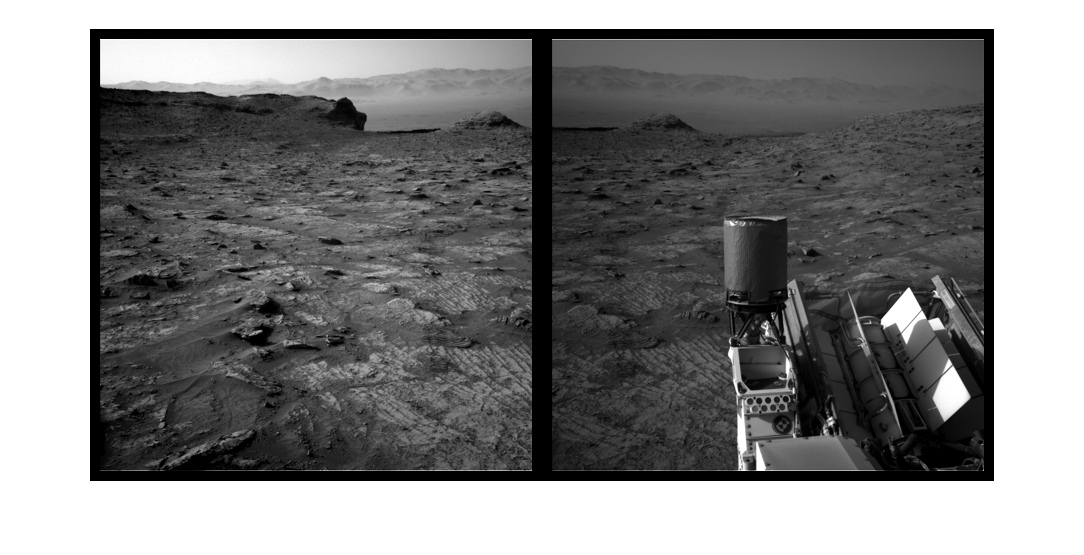

fixedImg = imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG");
movingImg = imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG");

montage({movingImg, fixedImg},"BorderSize",[10 10])

### Register the Images

Use the Registration Estimator app to create a function that registers the images. Then, use that function to return the registration structure.

When you're happy with your registration function, return to the course and use the online grader to check if it gives the correct result.

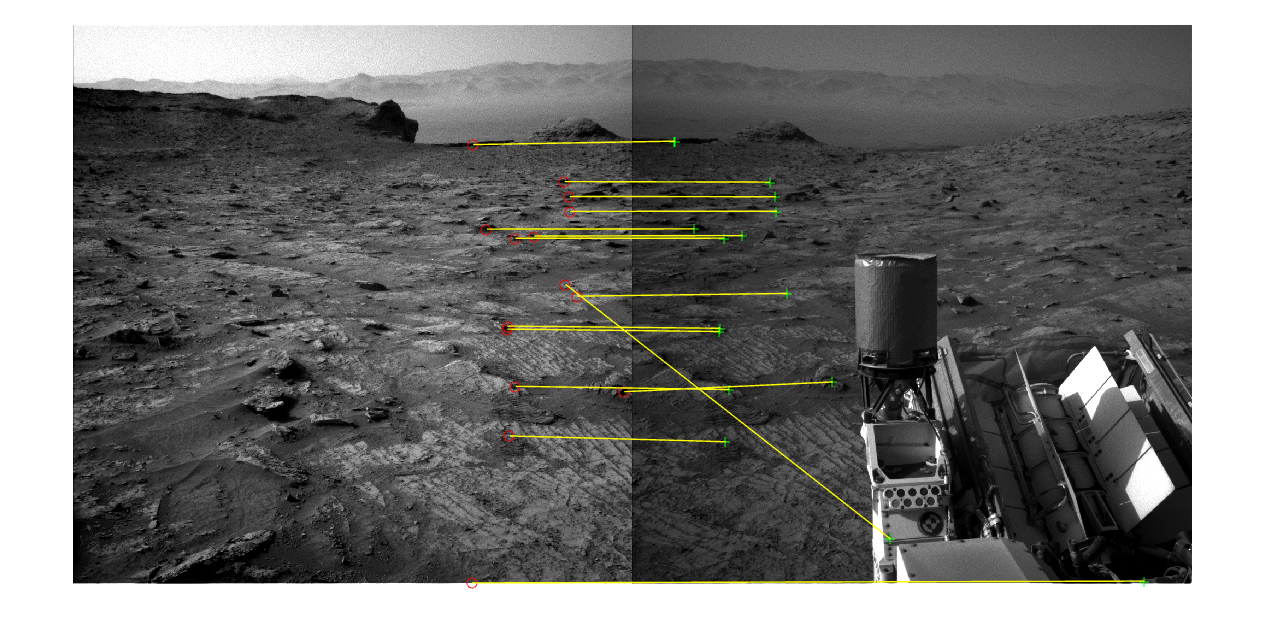

regOutput = registerImages(movingImg,fixedImg);

showMatchedFeatures(movingImg,fixedImg,regOutput.MovingMatchedFeatures,...
        regOutput.FixedMatchedFeatures,"montage");

movingT = regOutput.Transformation;
fixedT = rigidtform2d();

### Initialize the Panorama

Use your geometric transformation to determine the world coordinates and initialize an empty panorama image. Here, recall that you're working with **grayscale** images, unlike the color concrete images.

When you're done, return to the course and take the quiz to check if your panorama dimensions are as expected.

% Get the image size. Both images are the same size
[nrows, ncols, ~] = size(movingImg);
[xlimMoving, ylimMoving] = outputLimits(movingT,[1 ncols],[1 nrows])

xlimMoving = 1×2 single row vector
1.0e+03 *

   -1.0691    0.4022


ylimMoving = 1×2 single row vector
1.0e+03 *

   -0.1515    1.3969


[xlimFixed, ylimFixed] = outputLimits(fixedT,[1 ncols],[1 nrows])

xlimFixed =            1        1024


ylimFixed =            1        1024


% Find the smallest and largest extents in the world coordinate system
xMin = min([xlimMoving, xlimFixed]);
xMax = max([xlimMoving, xlimFixed]);
yMin = min([ylimMoving, ylimFixed]);
yMax = max([ylimMoving, ylimFixed]);
% Width and height of panorama.
w  = round(xMax - xMin);
h = round(yMax - yMin);

% Initialize the empty panorama. This is a color image.
panorama = zeros([h, w, 1],"uint8");

### Create the Panorama

Use the `vision.AlphaBlender `object to create the final panorama. When you're done, pass your final image to the `testMarsImage` function to see if it's correct. 

If you're correct, go back to the quiz and add the numeric code to complete the course!

If you get a dimension error while using `AlphaBlender`, double check that you are initializing the empty panorama correctly for a grayscale image. Remember that the third dimension of a color image has size 3, but the third dimension of a grayscale image only has size 1.

blender = vision.AlphaBlender("Operation","Binary Mask","MaskSource","Input port")

blender =   vision.AlphaBlender with properties:

         Operation: 'Binary mask'
        MaskSource: 'Input port'
    LocationSource: 'Property'
          Location: [1 1]


panoramaView = imref2d([h w],[xMin xMax],[yMin yMax])

panoramaView =   imref2d with properties:

           XWorldLimits: [-1.0691e+03 1024]
           YWorldLimits: [-151.5202 1.3969e+03]
              ImageSize: [1548 2093]
    PixelExtentInWorldX: 1.0001
    PixelExtentInWorldY: 1.0003
    ImageExtentInWorldX: 2.0931e+03
    ImageExtentInWorldY: 1.5485e+03
       XIntrinsicLimits: [0.5000 2.0935e+03]
       YIntrinsicLimits: [0.5000 1.5485e+03]


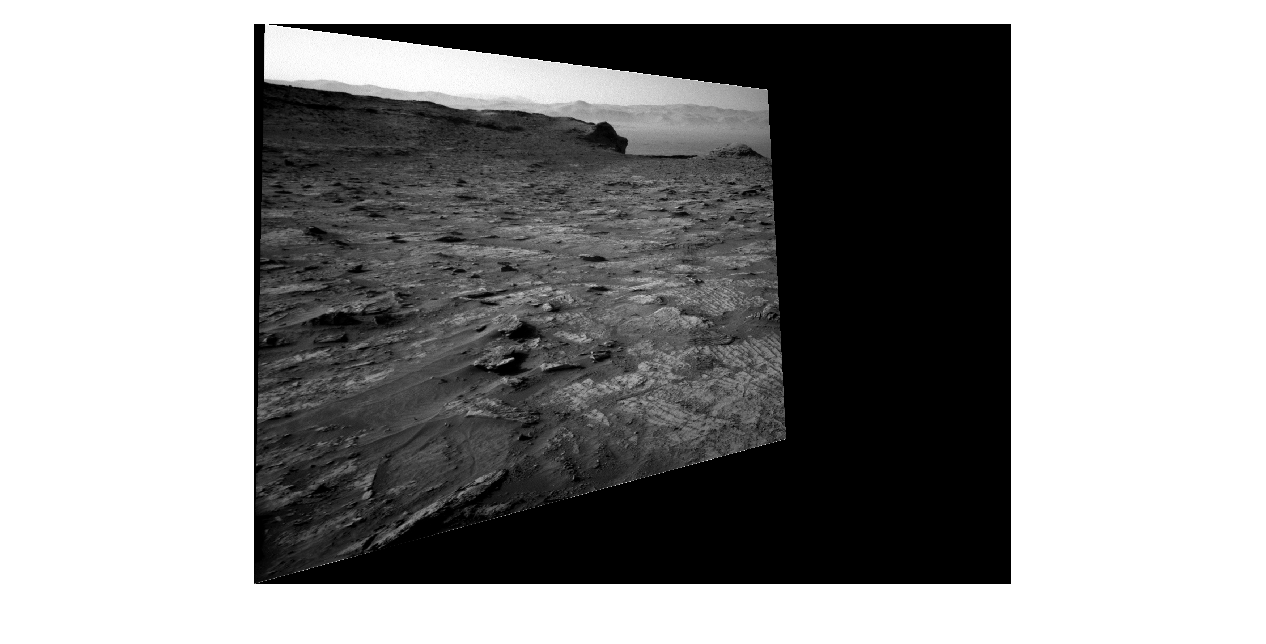

movingWarped = imwarp(movingImg,movingT,"OutputView",panoramaView);
fixedWarped = imwarp(fixedImg,fixedT,"OutputView",panoramaView);
imshow(movingWarped)

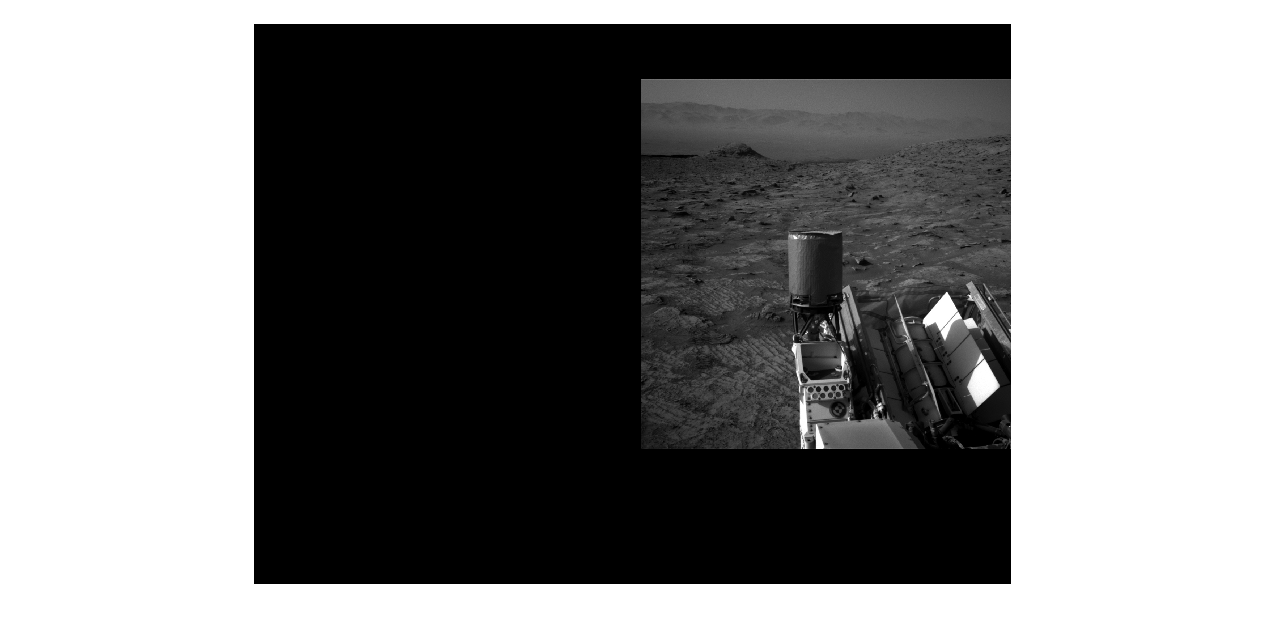

imshow(fixedWarped)

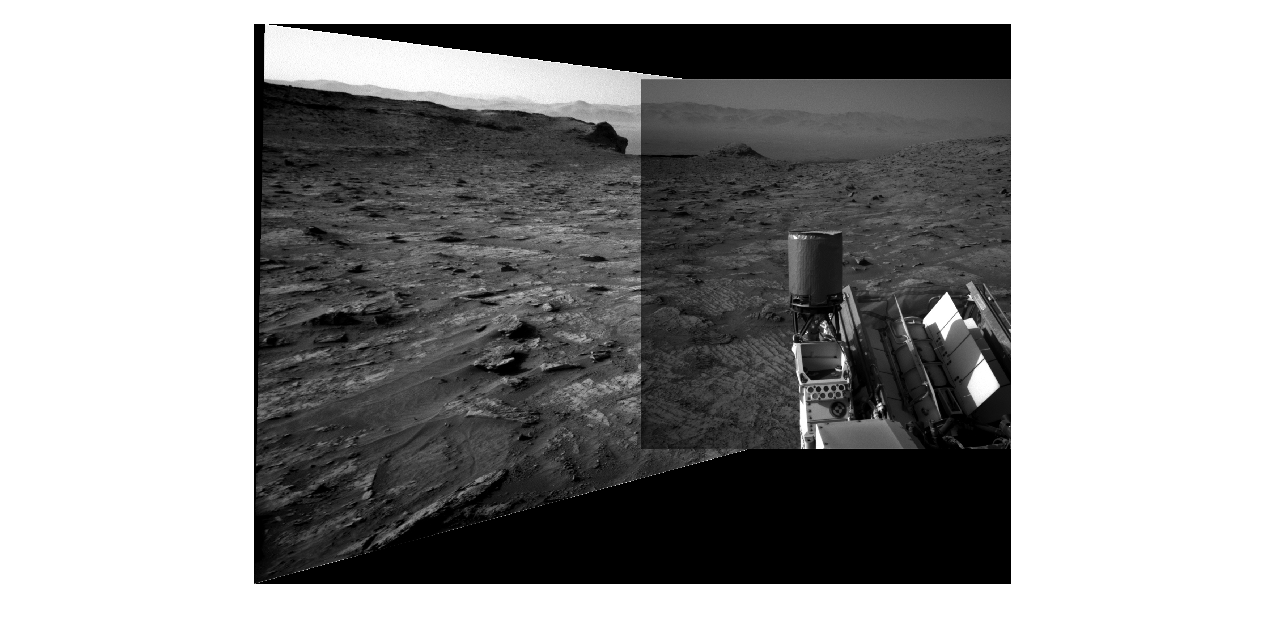

mask = ones(nrows, ncols, "logical");
fixedMask = imwarp(mask, fixedT, "OutputView", panoramaView);
movingMask = imwarp(mask, movingT, "OutputView", panoramaView);
% Add the first image to the panorama
panorama = blender(panorama,movingWarped,movingMask);
% Add the second image
panorama = blender(panorama,fixedWarped,fixedMask);
imshow(panorama)

*Copyright 2022 The MathWorks, Inc.*